# 034IN - FONDAMENTI DI AUTOMATICA - FUNDAMENTALS OF AUTOMATIC CONTROL - A.Y. 2023-2024

# Full Examination - June 21 2024

# PART 2 - Design of a Controller 

## Description of the Feedback Control System

Consider the feedback control system described by the block-scheme shown in the following figure

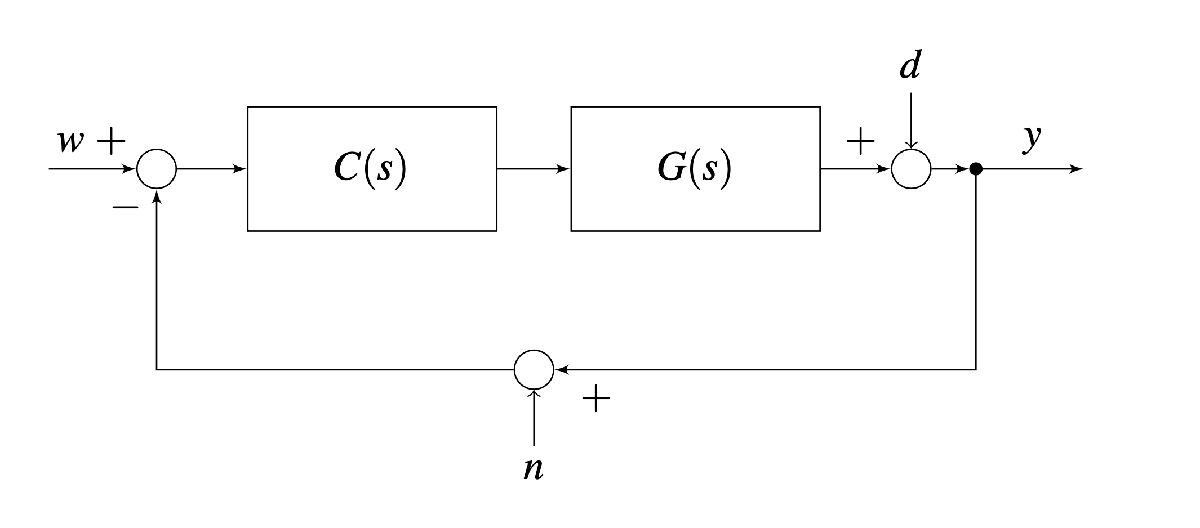	

where $G(s)$ is given by                


$$G(s) = \frac{4.815 \, (1+20\,s)}{(1+0.125\,s)^2}$$


## **Question**		

**Q1**: Design a controller $C(s)$ such that all following requirements are simultaneously met: 

- $\left\vert e(\infty) \right\vert = 0$ for $w(t) = \mathbf{1}(t)$, where $\mathbf{1}(t)$ denotes the unit step function; 

- For $d(t)=D \sin(\omega t) \cdot \mathbf{1}(t)$, $\forall D \in \mathbb{R}, \; D>0$, $\omega \in \left[0.1\,,\; 1.0\right]\;\text{rad/s}$, the corresponding steady-state output $y_{d,\,\infty}(t)$ generated by the disturbance $d(t)$, with $w(t)=0$, $n(t)=0$, $\forall t$ has magnitude satisfying $|y_{d,\,\infty}(t)| \le D/20$;

- For $n(t) = N \sin(\omega t) \cdot \mathbf{1}(t)$, $\forall N \in \mathbb{R},\;N>0$, $\omega \in \left[600,\,1200\right]\;\text{rad/s}$, the corresponding steady-state output $y_{n,\,\infty}(t)$ generated by the disturbance $n(t)$, with $w(t)=0$, $d(t)=0$, $\forall t$ has magnitude satisfying $|y_{n,\,\infty}(t)| \le N/25$.

- The phase margin satisfies $\varphi_m \ge 40^{\degree}$.

## Foreword to the Provided Solution

The proposed problem admits to more than one possible solution. The proposed solution is not the only admissible solution (in fact, the problem admits to infinite solutions), nor is it optimal. It is only a simple solution that can be obtained using the tools available in MATLAB's Control System Toolbox.

You are encouraged to solve the problem by finding alternative solutions and comparing the performance of the control system using your solution with those obtained using the proposed solution in this live script.  				

## Solution 

### A1: Answer to Question Q1

#### The Static Design					

To meet Requirement (Q1.1), the open-loop transfer function $L(s)$ has to be of type $g\ge 1$.  

We **choose **$g=1$ to keep the controller as simple as possible and, more important, to minimise the negative phase contribution that would reduce significantly the phase margin. 

Assuming 


$$C(s) = C_1(s) \cdot C_2(s)\,,\quad C_1(s) = \frac{\mu_C}{s}\,,\quad  C_2(0) =1$$


the **static design** leeds to 


$$L(s) = 4.815 \,\mu_{C}\,\frac{ (1+20\,s)}{s(1+0.125\,s)^2}$$


**Stability and Performance of the Closed-Loop System**

clear

% adding folders (and subfolders) to search path
addpath(genpath('BodeDiagram/'))

% let's define the transfer function builder element
s=tf('s');

Gs = 4.815*(1+20*s)/((1+0.125*s)^2); % the process G(s)

muC1 = 1; % first trial
C1s = muC1/s; % a pure I controller (the static controller)
C2s = tf(1); % the dynamic controller: a pure P gain
Cs = C1s * C2s;

L1s = Cs*Gs; % the open-loop TF
zL1 = zero(L1s);
pL1 = pole(L1s);

**First Analysis**: Explore the Root Locus of $L_1(s)$, looking for a feasible solution (i.e. by modifying only the gain constant of $C(s)$ am I able to meet all the requirements?)

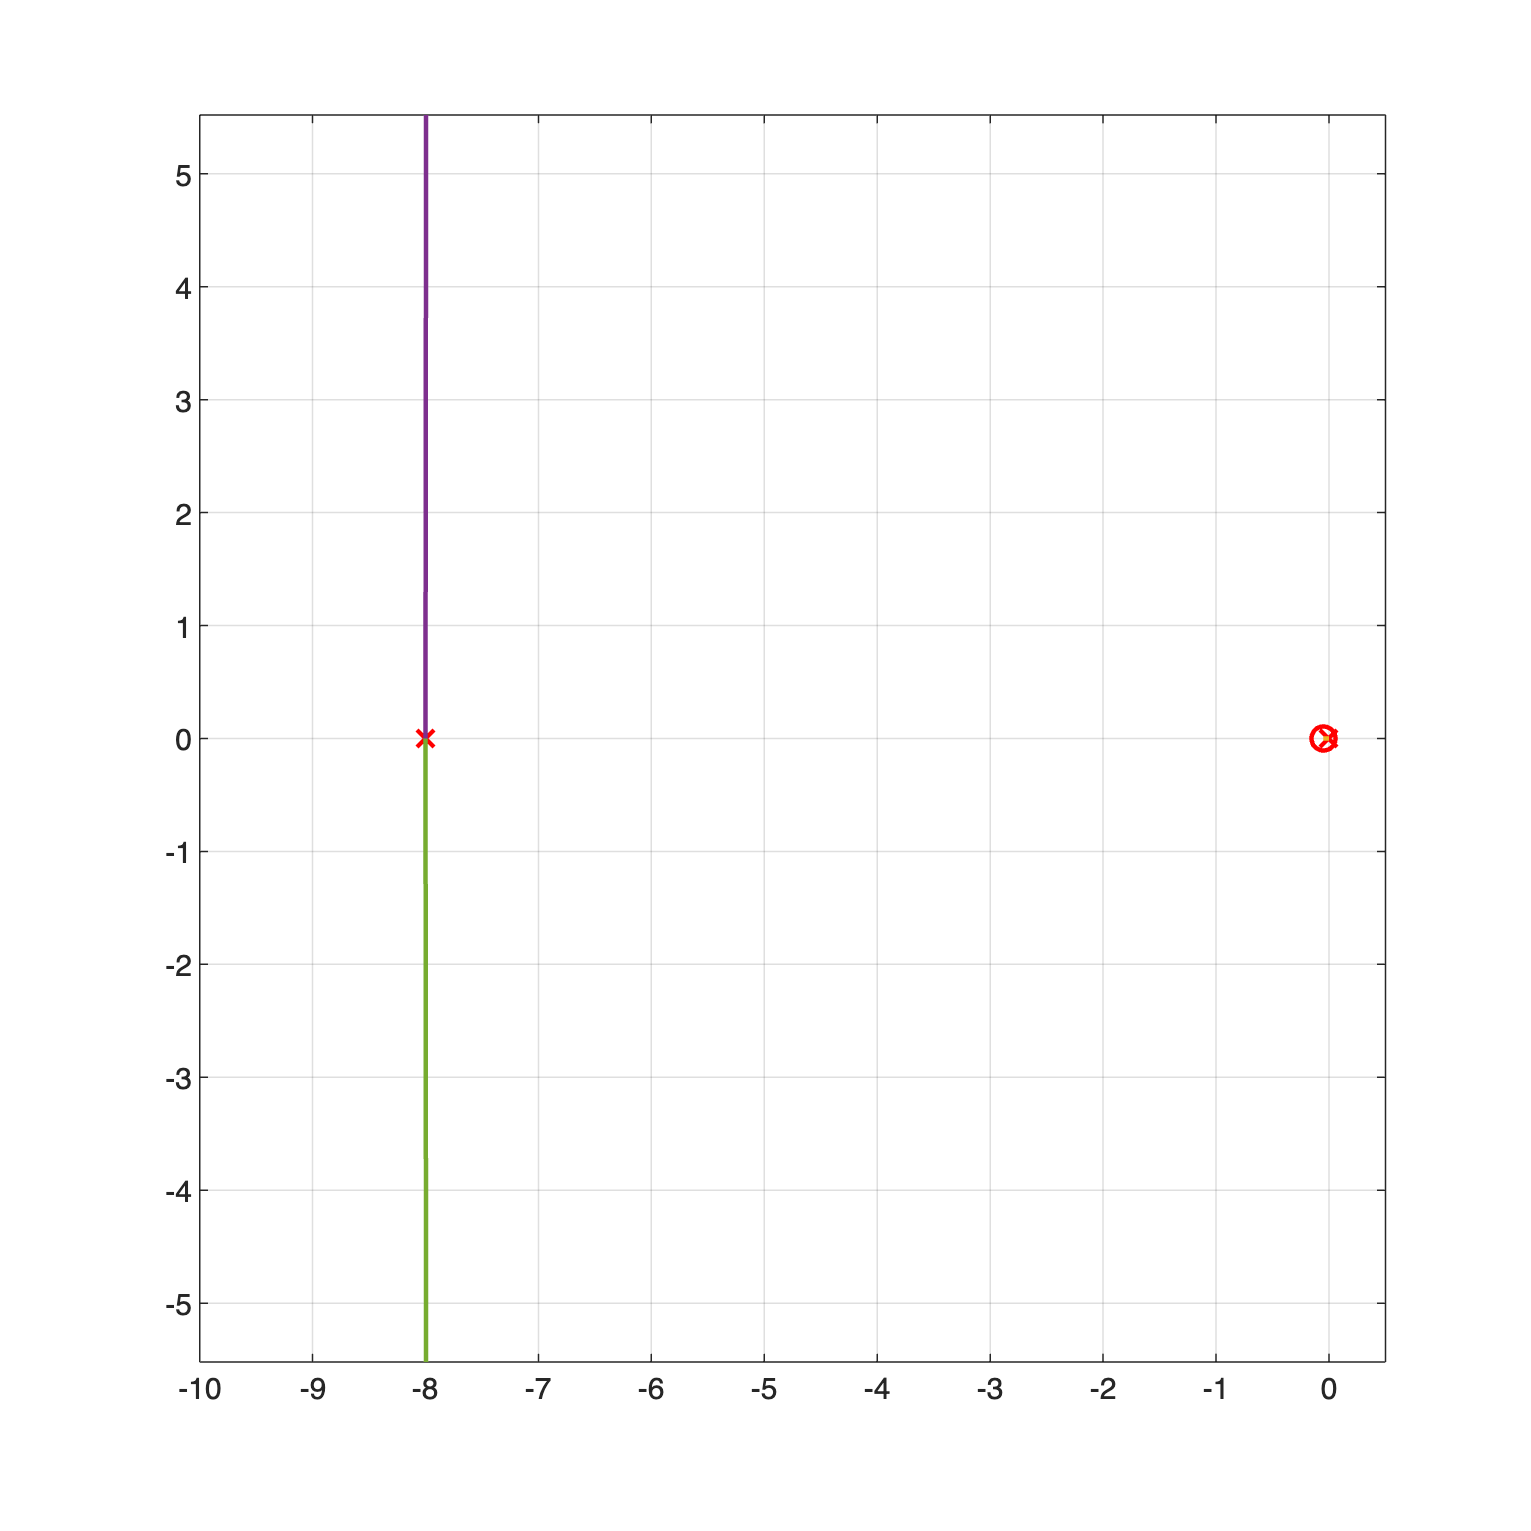

rhoSET = linspace(0, 1e3, 1e4); 
% 10000 values for the gain rho in the Direct RL
% starting from the min value that allows to meet 
% the requirement (Q1.1)
[DRL_L1, ~] = rlocus(L1s, rhoSET);

figure('Units','centimeters', 'Position',[0.1,0.1, 18, 18]);
% let's start with zeros & poles 
h_s1 = plot(real(zL1),imag(zL1),'ro', ...
    real(pL1),imag(pL1),'rx', ...
    'MarkerSize',8, 'LineWidth',1.5); 
hold on;
% L1s is a TF with only 1 zero and 1 pole, 
% so there are no singular points, no centroid,
% and no asymptotes.

% the Direct RL
for n=1:size(DRL_L1,1)
    h_rld1 = plot( real(DRL_L1(n,:)),imag(DRL_L1(n,:)), ...
               'LineWidth',1.5 );
end
grid on; hold off; axis equal;
zoom on; xlim([-10, +0.5]);

**Remark**: the closed-loop system is asymptotically stable $\forall \mu_{C} > 0$.

**The Bode Diagrams**

Let's explore the Bode Frequency Response Diagram:

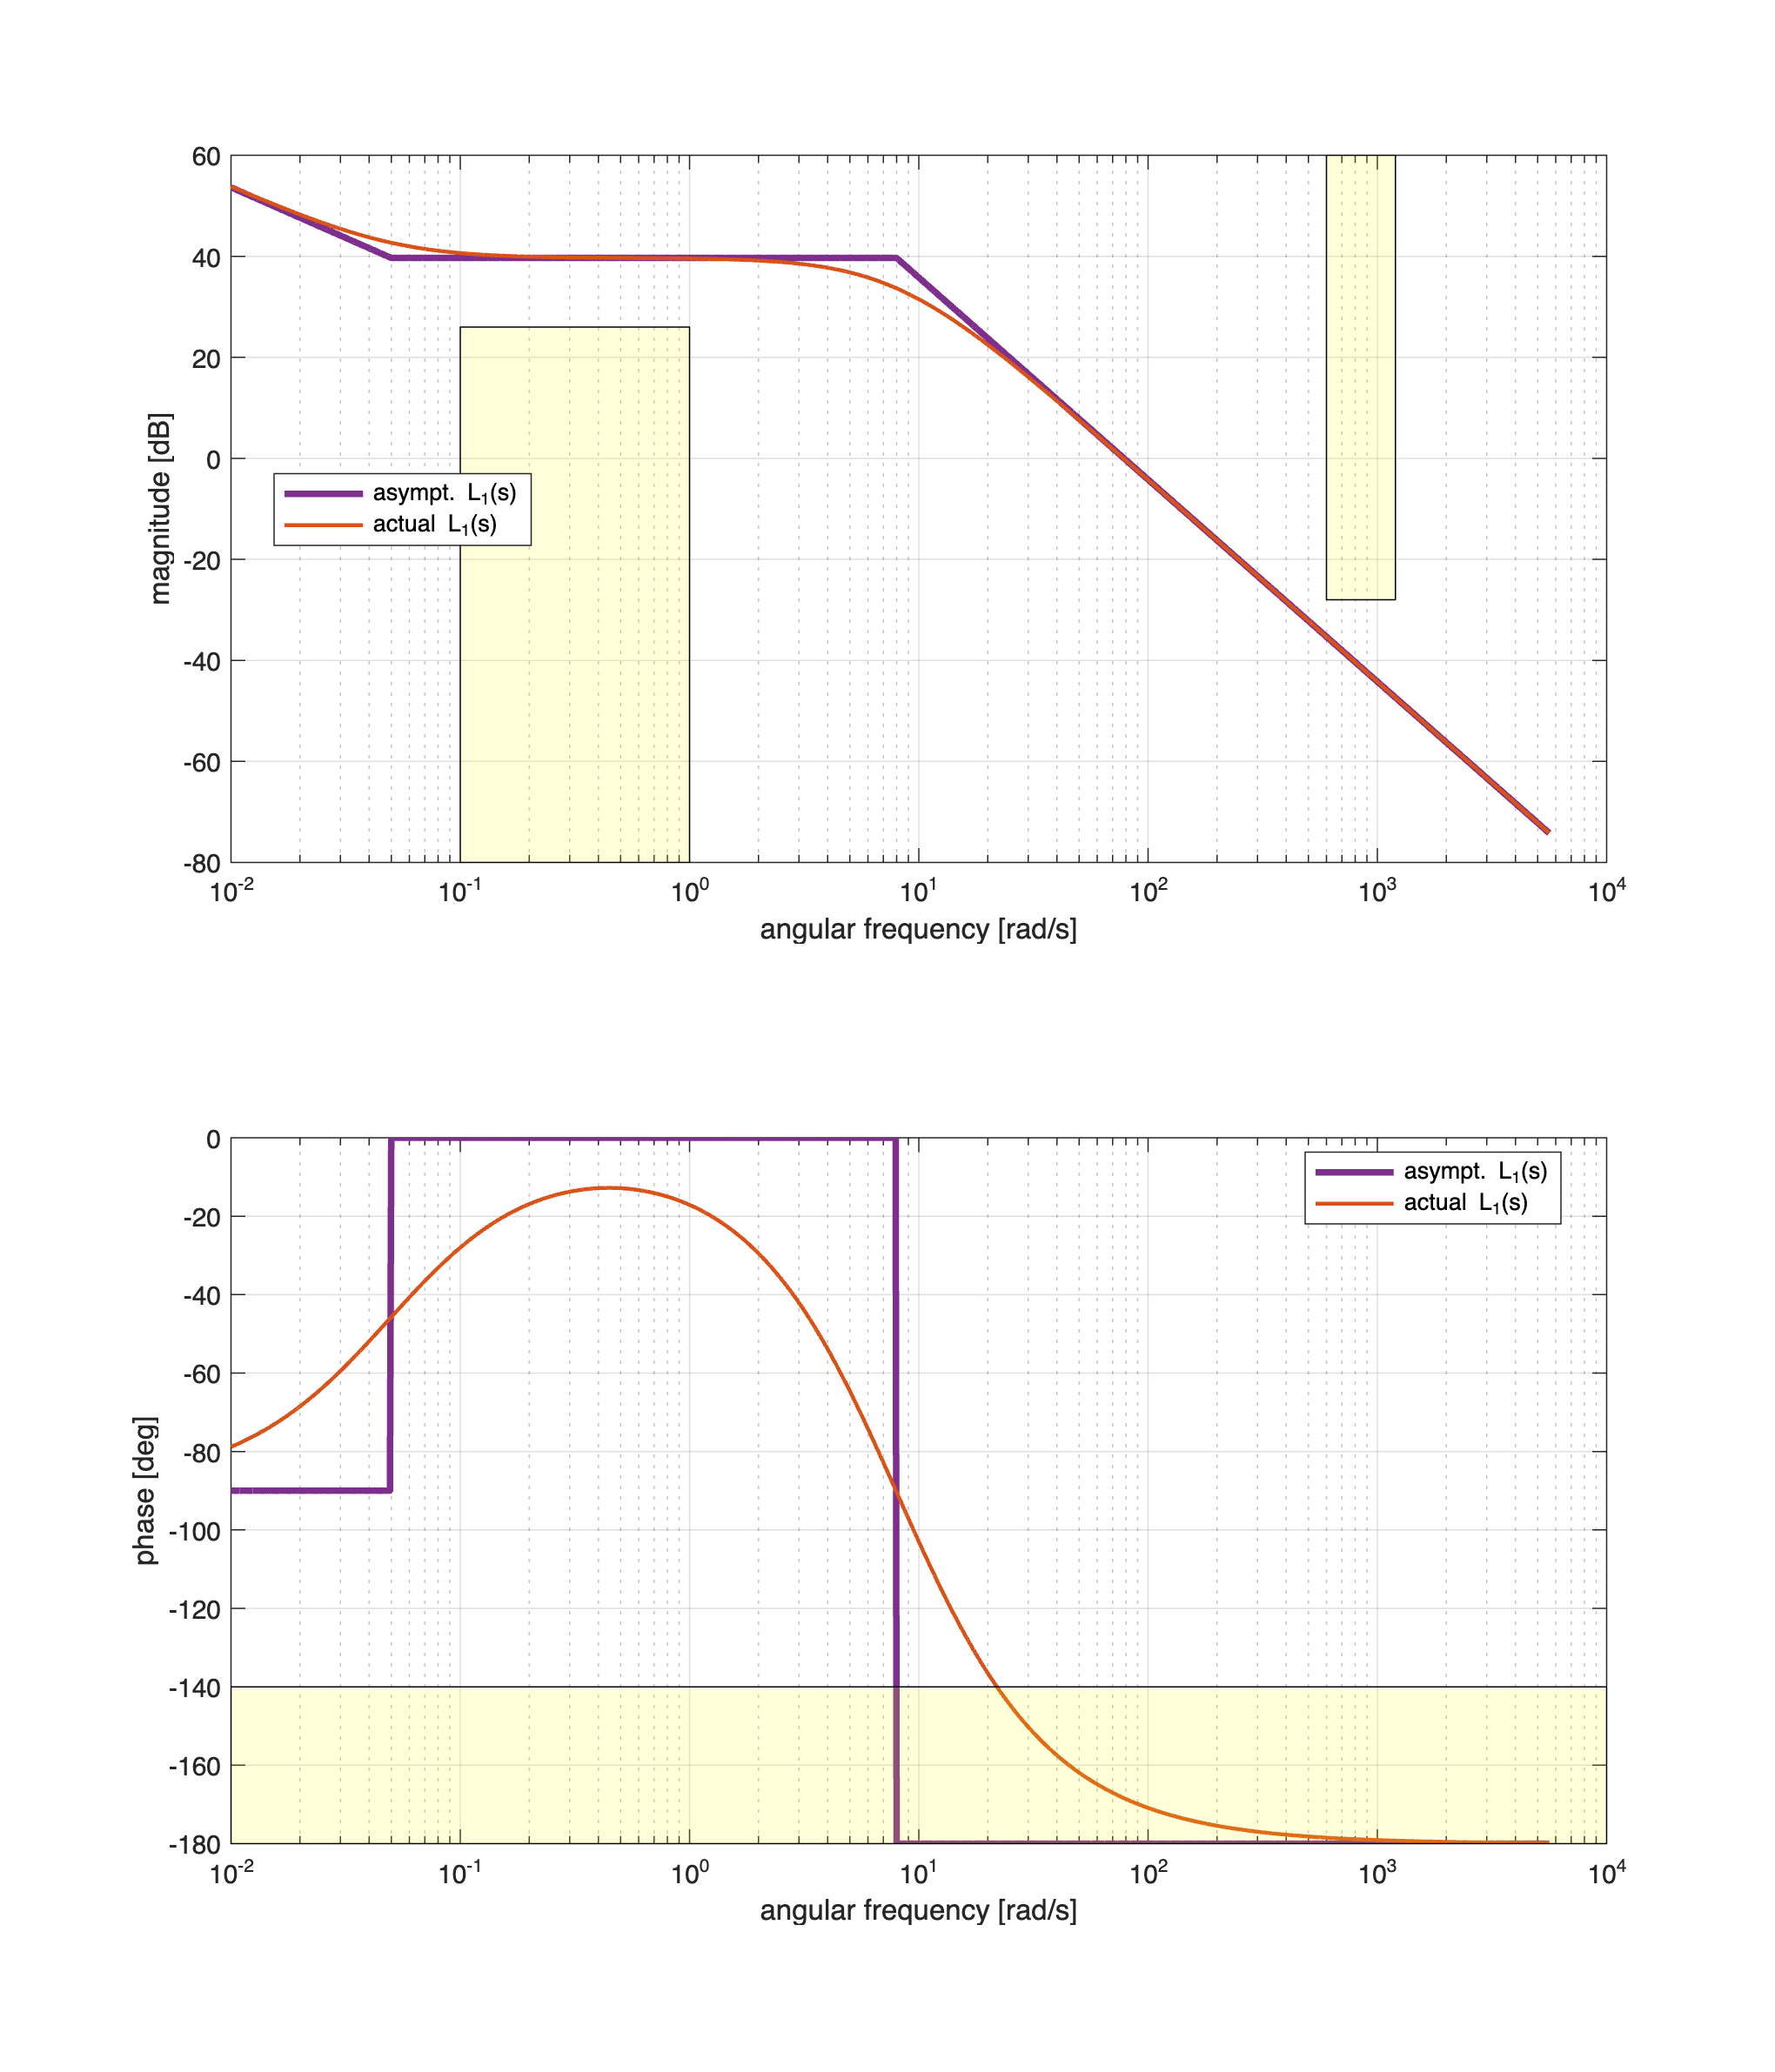

omVALS = logspace(-2,3.75, 1e5); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-1 and 10^2 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                  % for the actual diagrams

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

[hax1, hax2] = drawBodediagrams(L1s, omVALS, Bcolors(3, :), 2.5, '-', ...
                       Bcolors(6, :), 1.5, '-', hf);

% the (Q1.2) constraint
minOmega1 = 0.1;
maxOmega1 = 1.0;
LMINdB = +26; % dB
YLIMs = ylim(hax1);
Vert1 = [minOmega1 , YLIMs(1); minOmega1 , LMINdB; ...
         maxOmega1 , YLIMs(1); maxOmega1 , LMINdB];
Faces1 = [1  2  4  3];
hold on;
patch(hax1, 'Faces',Faces1,'Vertices',Vert1,...
        'FaceColor','yellow','FaceAlpha',.15);
% the (Q1.3) constraint
minOmega2 = 600.0;
maxOmega2 = 1200.0;
LMAXdB = -28; % dB
YLIMs = ylim(hax1);
Vert2 = [minOmega2 , LMAXdB; minOmega2 , YLIMs(2) ; ...
         maxOmega2 , YLIMs(2); maxOmega2 , LMAXdB];
Faces2 = [1  2  3  4];
patch(hax1, 'Faces',Faces2,'Vertices',Vert2,...
        'FaceColor','yellow','FaceAlpha',.15);

% the (Q1.4) constraint
XLIMs = xlim(hax2);
YLIMs = ylim(hax2);
minOmega2 = min(XLIMs);
maxOmega2 = max(XLIMs);
argLMIN = -140; % arg(L(j omega)) >= -140 <==> phase margin >= 40

Vert2 = [minOmega2 , YLIMs(1); minOmega2 , argLMIN ; ...
         maxOmega2 ,argLMIN ; maxOmega2 , YLIMs(1)];
Faces2 = [1  2  3  4];
patch(hax2, 'Faces',Faces2,'Vertices',Vert2,...
        'FaceColor','yellow','FaceAlpha',.15);

legend(hax1,  'asympt. L_1(s)', 'actual L_1(s)', ...
             'Location', 'best');

legend(hax2,  'asympt. L_1(s)', 'actual L_1(s)', ...
             'Location', 'best');

The dynamic requirements are not completely fulfilled:

- according to (Q1.2) $\left\vert L(j\,\omega)\right\vert \ge 26\,\text{dB} \, , \; \omega \in \left[0.1\,,\; 1.0\right]\; \text{rad/s}$. This requirement could be easily fulfilled, by adjusting the gain constant $\mu_C$;

- according to (Q1.3) $\left\vert L(j\,\omega)\right\vert \le -28\,\text{dB} \, , \; \omega \in \left[600.0\,,\; 1200.0\right]\; \text{rad/s}$.  

- according to (Q1.4) $\omega_C \le 20\;\text{rad/s}$ (i.e., the ultimate angular frequency value that allows for fulfilling the phase margin requirement $\varphi_m \ge 40^{\circ}$). 

**Important Remark**

Using the actual controller, we cannot meet this requirement unless we no longer meet the former requirements. The actual $\omega_C$ is close to $80$ rad/s; to move it back to $20$ rad/s or less, we must decrease the gain $\mu_C$. By inspecting the Bode plot of the frequency response's magnitude, the actual amplitude corresponding to the angular frequency  $\bar \omega = 20$ rad/s is (more or less) $20$ dB. If we decrease $\mu_C$ by subtracting $20$ dB or more, the new crossover frequency will be less than or equal to $20$ rad/s, but then the magnitude plot will enter the "forbidden" yellow zone in the frequency range $[0.1,\,1.0]$ rad/s. Thus we cannot meet all the requirements using this approach.

Let's modify the controller $C(s)$, by modifying the gain $\mu_C$ and introducing some zeros and poles in the dynamic controller $C_2(s)$.

#### The Dynamic Design	

Let's start with $C_2(s) = \frac{(1+0.125\,s)^2}{(1+0.25\,s)\,(1+0.01\,s)}$. 

- The **key idea** is to keep the "almost constant" amplification of $L(j\omega)$ in the range $ \omega \in \left[0.1\,,\; 1.0\right]\; \text{rad/s}$, but then to improve the attenuation when $\omega \ge 100$ rad/s.

- **Note** the structure of $C_2(s)$: we removed the coincident poles at $p_{1,\,2}=-8$ rad/s and insert two distinct poles, one at $\hat p_1= -4$ and the second one at $\hat p_2 = -100$.

- The two new poles are more than a decade apart. Thus the effect of the second pole at frequencies relatively close to those of the first pole is negligible.

- **The plan**: Suppose the crossover frequency falls in the -20 dB/decade slope segment  (of the Bode asymptotic diagram of the frequency response modulus) starting at the angular frequency $\hat \omega = 4$ . In that case, the corresponding phase margin will be high: greater than or equal to $90^{\circ}$ if the $\omega_C$ falls at or very close to that of pole $\hat p_1$, greater than or equal to $45^{\circ}$ if it falls very close to that of the next pole (i.e. $\hat p_2$). **This strategy could succeed in completing the controller design**.

The open-loop transfer function $L(s)$ is:


$$\begin{array}{rcl}
C_1(s) &=& \frac{\mu_C}{s}\;, \quad \mu_C>0
\\
C_2(s) &=& \frac{(1+0.125\,s)^2}{(1+0.25\,s)\,(1+0.01\,s)}
\end{array} \quad \Longrightarrow \quad L_2(s) = C_1(s) \cdot C_2(s) \cdot G(s) = 4.815\,\mu_C \cdot\frac{(1+20\,s)}{s(1+0.25\,s)\,(1+0.01s)}$$


**Tuning the Gain - Step 0: The Asymptotic Magnitude Approximation**

How to tune $\mu_C$? Consider the expression of the **frequency response magnitude**:


$$\left| L_2(j \omega) \right| = 4.815\cdot \mu_C \cdot \frac{ \left|1+j\,20\,\omega \right|}{\omega\, \left|1+j\,\frac{\omega}{4} \right| \, \left|1+j\,\frac{\omega}{100} \right|$$


and compute the **asymptotic** **approximation**, according to the rules explained in **Part 8, pp. 21 - 35** of the course material


$$\begin{array}{rcrclcl}
0<\omega\le\frac{1}{20} & \Longrightarrow & \left|L_2(j \omega) \right|_{\text{dB}} &\approx& 20\,\log_{10} 4.815\cdot \mu_C -20\,\log_{10}\omega + 20\,\log_{10} 1 - 20\,\log_{10} 1- 20\,\log_{10} 1 &=& 13.65+20\,\log_{10} \mu_C  -20\,\log_{10}\omega \\
\frac{1}{20}<\omega\le 4 &\Longrightarrow & \left|L_2(j \omega) \right|_{\text{dB}} &\approx&20\,\log_{10} 4.815\cdot \mu_C -20\,\log_{10}\omega + 20\,\log_{10} 20\omega  - 20\,\log_{10} 1- 20\,\log_{10} 1 &=& 39.67+20\,\log_{10} \mu_C  \\
4 <\omega \le 100 &\Longrightarrow & \left|L_2(j \omega) \right|_{\text{dB}} &\approx&20\,\log_{10} 4.815\cdot \mu_C -20\,\log_{10}\omega + 20\,\log_{10} 20\omega  - 20\,\log_{10} \frac{\omega}{4}  - 20\,\log_{10} 1 &=& 
51.71 +20\,\log_{10} \mu_C -20\,\log_{10} \omega \\
100 < \omega &\Longrightarrow & \left|L_2(j \omega) \right|_{\text{dB}} &\approx&20\,\log_{10} 4.815\cdot \mu_C -20\,\log_{10}\omega + 20\,\log_{10} 20\omega  - 20\,\log_{10} \frac{\omega}{4}  - 20\,\log_{10} \frac{\omega}{100} &=&  
91.71 +20\,\log_{10} \mu_C -40\,\log_{10} \omega
\end{array}$$


where


$$20\,\log_{10} 4.815 \approx 13.65 \, \text{dB} \;, \quad 20\,\log_{10} 4\approx 12.04 \, \text{dB} \;, \quad 20\,\log_{10} 20\approx 26.02 \, \text{dB} \;, \quad 20\,\log_{10} 100 = 40 \, \text{dB} $$


**Tuning the Gain - Step 1: Determine the Gain Exploiting the Asymptotic Bode DIagrams**

- Let's suppose this: the straight line corresponding to the last portion of the asymptotic Bode diagram of the frequency response amplitude takes on a value of $0$ dB when $\omega = 100$ rad/s. This means $\omega_C$ is approximately 100 rad/s, and the phase margin $\varphi_m$ is higher than or equal to $45^{\circ}$ (according to the previously performed analysis). Let's verify that 


$$\arg L_2(j 100) \ge -135^{\circ}$$


muC1 = 1.0; % any positive gain value

C1s = muC1/s; % a pure I controller (the static controller)

C2s = (1+0.125*s)^2/(1+0.25*s)/(1+0.01*s); % the dynamic controller

Cs = C1s * C2s;

L2s = minreal(Cs*Gs); % the open-loop TF

rad2deg(angle(freqresp(L2s, 1j*100)))

ans = -132.7380

( rad2deg(angle(freqresp(L2s, 1j*100))) >= -135) % logical test - you can also use assert( )

ans = logical
   1

- Thus $\bar \omega = 100$ could be a good candidate for the crossover frequency $\omega_C$! 

- Of course, the proposal must meet all the requirements. 

- Nevertheless, you cannot verify the fulfilment of the requirements until you have computed the gain $\bar \mu_C$, allowing the proposed angular frequency $\bar \omega$ to be the effective crossover frequency $\omega_C$ for the system $L_2(s)$.

- Thus, let's compute $\bar \mu_C$:

Recall 


$$100 < \omega \;\Longrightarrow \; \left|L_2(j \omega) \right|_{\text{dB}} \;\approx 
91.71 +20\,\log_{10} \mu_C -40\,\log_{10} \omega$$


Thus, by imposing $\bar \omega$ as crossover frequency we obtain an equation involving $\bar \mu_C$


$$\left|L_2(j \bar \omega) \right|_{\text{dB}} = 91.71 +20\,\log_{10} \mu_C -40\,\log_{10} \bar \omega =  0 \; \Longrightarrow \; 
20\,\log_{10} \mu_C = -91.71 + 40\,\log_{10} 100 = -11.714 \; \Longrightarrow \; \log_{10} \mu_C \approx -0.586 $$


Finally


$$\bar \mu_C = 10^{-0.586} \approx 0.259$$


barMUc = 10^( -(91.71-40*log10(100))/20 )

barMUc = 0.2597

**Tuning the Gain - Step 2: Check the Feasibility of the Proposal**

Are all requirements met by the application of the proposed gain value $\bar \mu_C$?

- Q1.1 : the static controller is $C_1(s) = \frac{\mu_C}{s}$, thus the requirement is fulfilled.

- Q1.4 : we already verified that imposing $\mu_C = \bar \mu_C$ the phase margin meets the requirement.

- We should check whether requirements Q1.2 and Q1.3 are fulfilled.

There are two alternatives:

- exploiting the mathematical expression of the straight lines composing the asymptotic Bode diagram of the frequency response's magnitude, verify that the frequency response always stays out of the "forbidden regions" corresponding to the magnitude constraints.

- plot the Bode diagrams of the frequency response using $\mu_C = \bar \mu_C$, and draw the regions corresponding to the constraints on the magnitude of the frequency response. Finally, verify by inspection that the Bode diagram doesn't cross the "forbidden regions" describing the constraints.

**Feasibility Exploiting the Mathematical Expression of the Asymptotic Bode Diagram Straight Lines**

- According to (Q1.2) $\left\vert L(j\,\omega)\right\vert \ge 26\,\text{dB} \, , \; \omega \in \left[0.1\,,\; 1.0\right]\; \text{rad/s}$. Thus the involved asymptotic straight line portion of the Bode diagram is


$$\omega \in \left[0.1\,,\; 1.0\right]\; \subset \left[0.05\,,\; 4\right] \quad \Longrightarrow \quad \left|L_2(j \omega) \right|_{\text{dB}} \approx 39.67+20\,\log_{10} \bar \mu_C $$


L_MAGQ1_2 = +26; % the minimum amplitude value according req Q1.2
y_dB = 39.67+20*log10(barMUc)

y_dB = 27.9600

reqQ1_2_FLAG = (y_dB >= L_MAGQ1_2);

- According to (Q1.3) $\left\vert L(j\,\omega)\right\vert \le -28\,\text{dB} \, , \; \omega \in \left[600.0\,,\; 1200.0\right]\; \text{rad/s}$.  . Thus the involved asymptotic straight line portion of the Bode diagram is


$$\omega \in \left[600.0\,,\; 1200.0\right] \subset [100\,,\; +\infty) \quad \Longrightarrow \quad \left|L_2(j \omega) \right|_{\text{dB}} \approx
91.71 +20\,\log_{10} \bar  \mu_C -40\,\log_{10} \omega$$


L_MAGQ1_3 = -28; % the maximum amplitude value according req Q1.3
OMleft =600; % rad/s
y_dB = 91.71+20*log10(barMUc)-40*log10(OMleft)

y_dB = -31.1261

reqQ1_3_FLAG = (y_dB <= L_MAGQ1_3);
if (reqQ1_2_FLAG && reqQ1_3_FLAG)
    disp('The solution is feasible!')
else
    disp('The solution is unfeasible!')
end

The solution is feasible!


**Feasibility by Visual Inspection on the Bode Diagram**

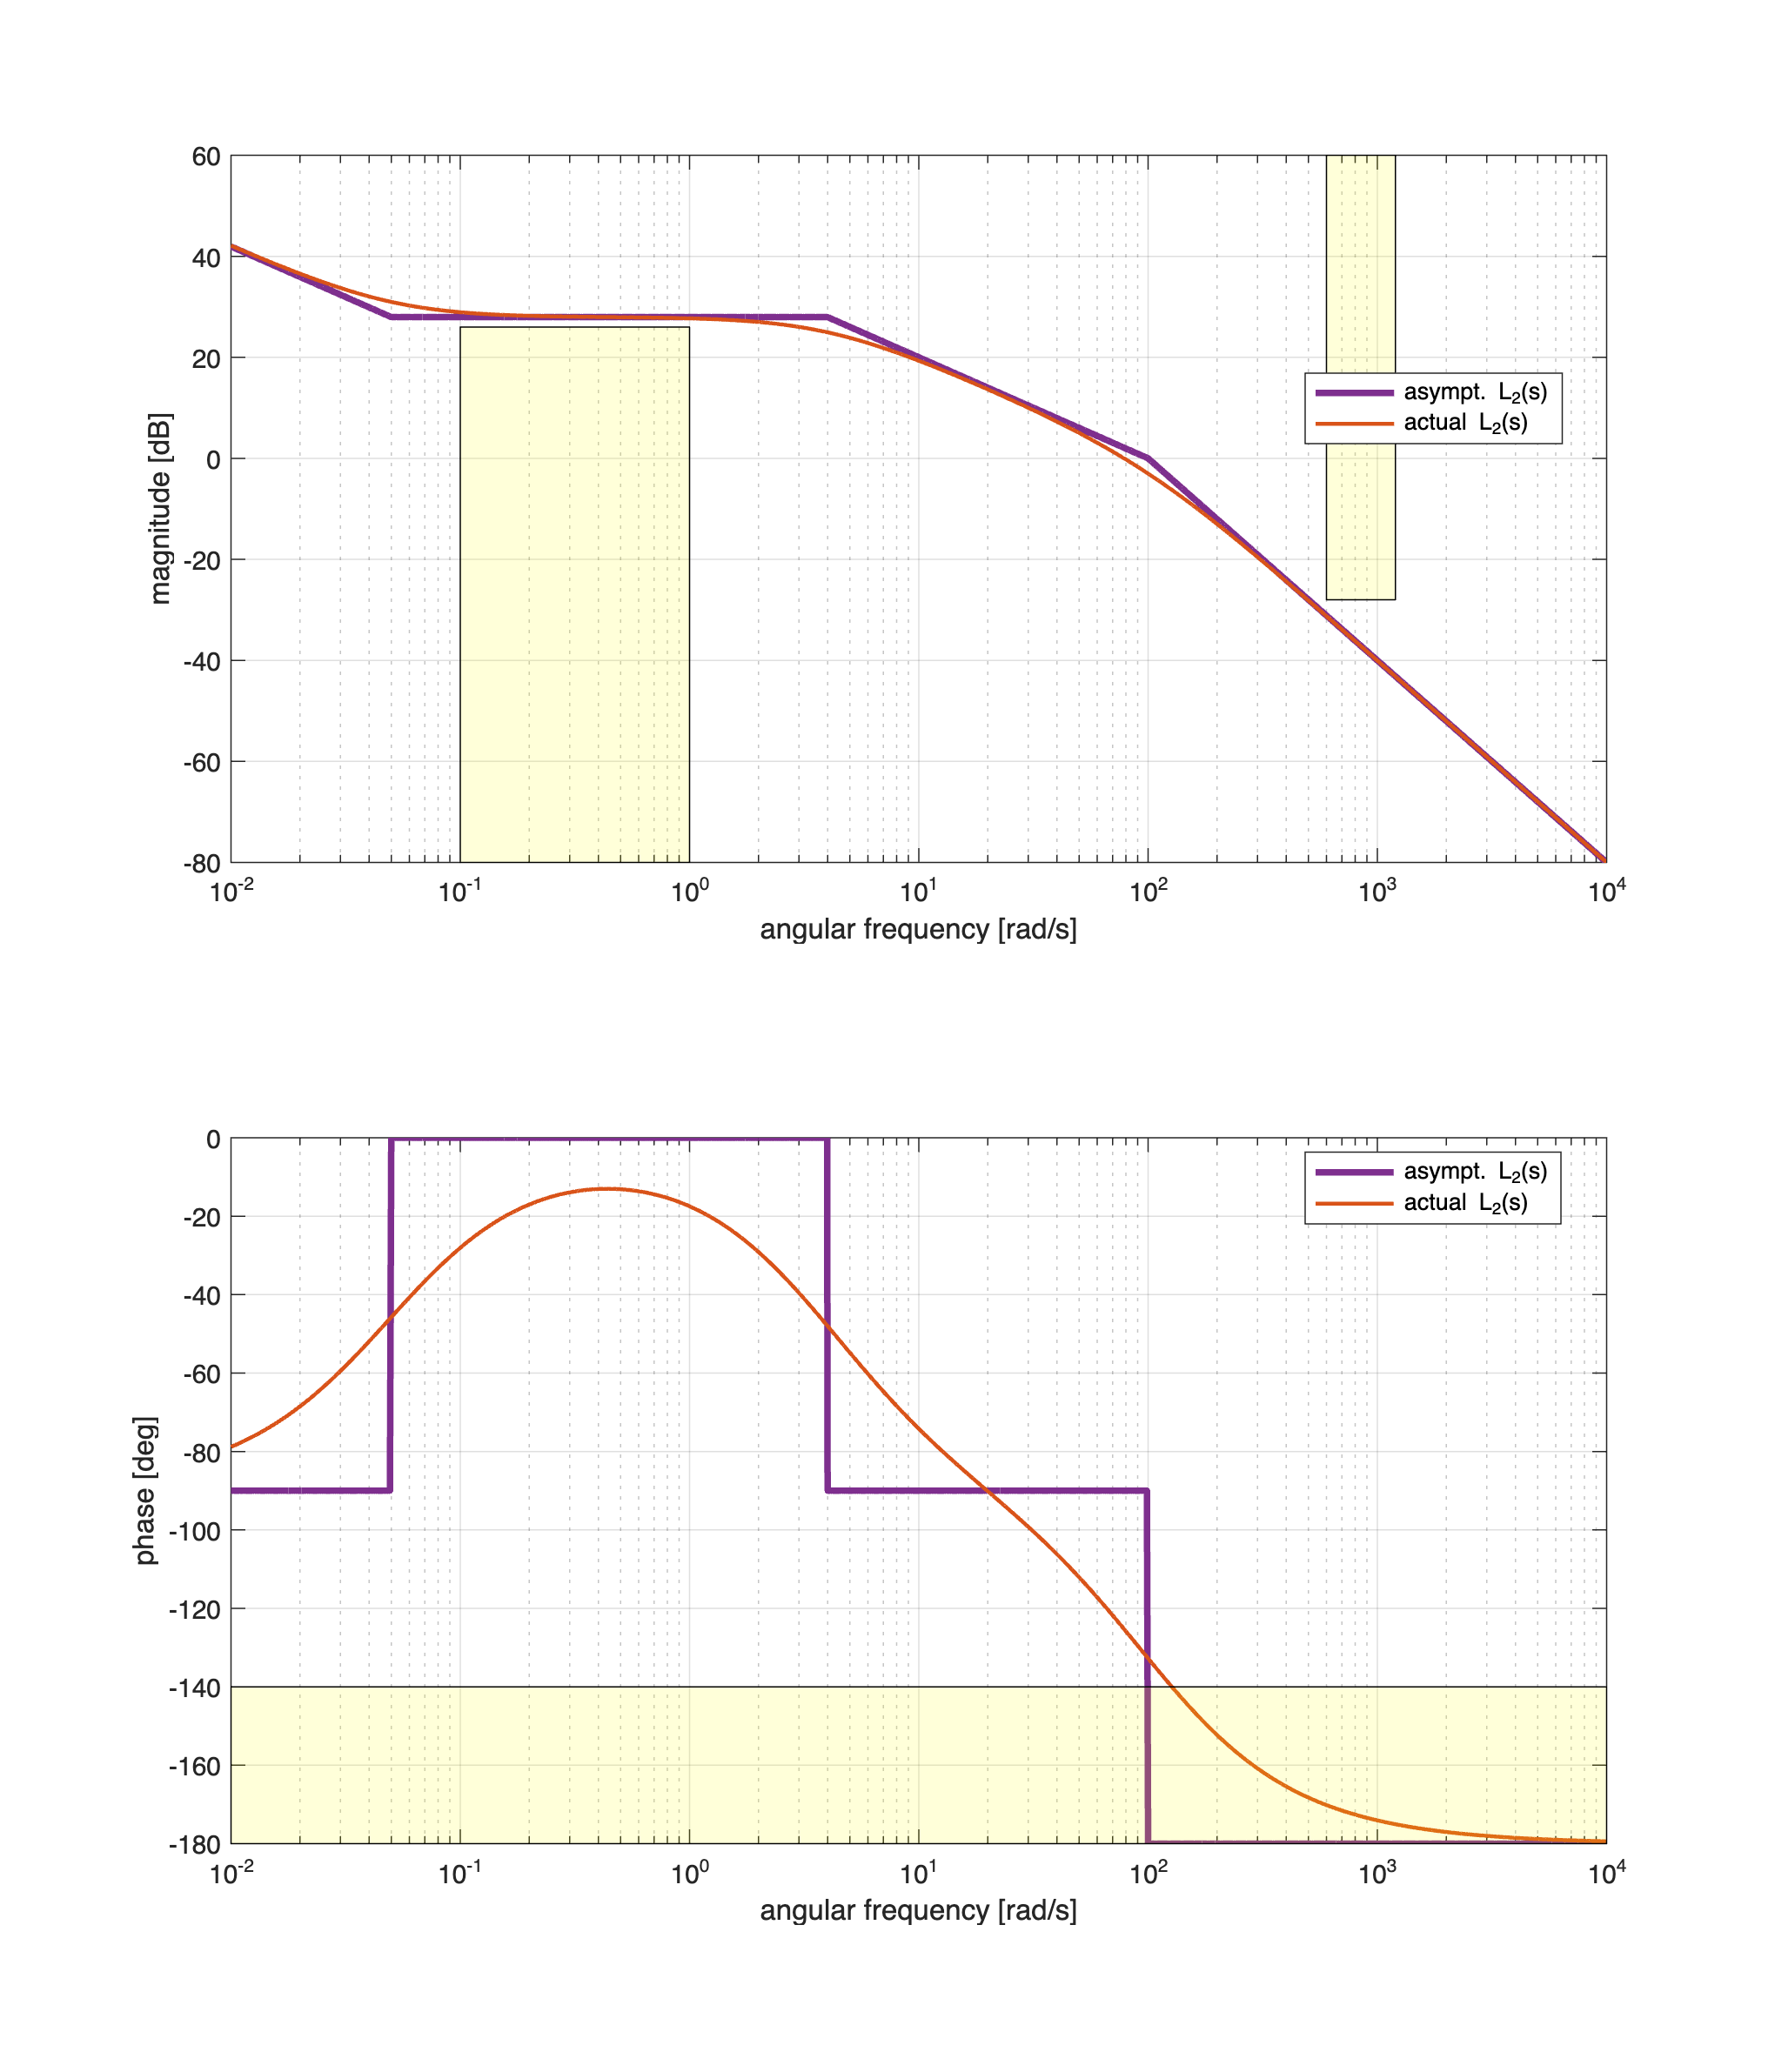

muC1 = barMUc; % the new gain value, as computed according to the above described procedure

C1s = muC1/s; % a pure I controller (the static controller)

C2s = (1+0.125*s)^2/(1+0.25*s)/(1+0.01*s); % the dynamic controller

Cs = C1s * C2s;

L2s = minreal(Cs*Gs); % the open-loop TF
zL2 = zero(L2s);
pL2 = pole(L2s);

omVALS = logspace(-2,4, 1e5); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-1 and 10^2 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                  % for the actual diagrams

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

[hax1, hax2] = drawBodediagrams(L2s, omVALS, Bcolors(3, :), 2.5, '-', ...
                       Bcolors(6, :), 1.5, '-', hf);
% the (Q1.2) constraint
minOmega1 = 0.1;
maxOmega1 = 1.0;
LMINdB = +26; % dB
YLIMs = ylim(hax1);
Vert1 = [minOmega1 , YLIMs(1); minOmega1 , LMINdB; ...
         maxOmega1 , YLIMs(1); maxOmega1 , LMINdB];
Faces1 = [1  2  4  3];
hold on;
patch(hax1, 'Faces',Faces1,'Vertices',Vert1,...
        'FaceColor','yellow','FaceAlpha',.15);
% the (Q1.3) constraint
minOmega2 = 600.0;
maxOmega2 = 1200.0;
LMAXdB = -28; % dB
YLIMs = ylim(hax1);
Vert2 = [minOmega2 , LMAXdB; minOmega2 , YLIMs(2) ; ...
         maxOmega2 , YLIMs(2); maxOmega2 , LMAXdB];
Faces2 = [1  2  3  4];
patch(hax1, 'Faces',Faces2,'Vertices',Vert2,...
        'FaceColor','yellow','FaceAlpha',.15);

% the (Q1.4) constraint
XLIMs = xlim(hax2);
YLIMs = ylim(hax2);
minOmega2 = min(XLIMs);
maxOmega2 = max(XLIMs);
argLMIN = -140; % arg(L(j omega)) >= -140 <==> phase margin >= 40

Vert2 = [minOmega2 , YLIMs(1); minOmega2 , argLMIN ; ...
         maxOmega2 ,argLMIN ; maxOmega2 , YLIMs(1)];
Faces2 = [1  2  3  4];
patch(hax2, 'Faces',Faces2,'Vertices',Vert2,...
        'FaceColor','yellow','FaceAlpha',.15);


legend(hax1,  'asympt. L_2(s)', 'actual L_2(s)', ...
             'Location', 'best');

legend(hax2,  'asympt. L_2(s)', 'actual L_2(s)', ...
             'Location', 'best');

- The solution is feasible! 

- The Bode diagram of the frequency response magnitude stays out of the "forbidden regions" corresponding to the magnitude constraints.

- The crossover angular frequency allows to obtain a phase margin fulfilling the Q1.4 requirement.

#### The Effective Phase and Gain Margins

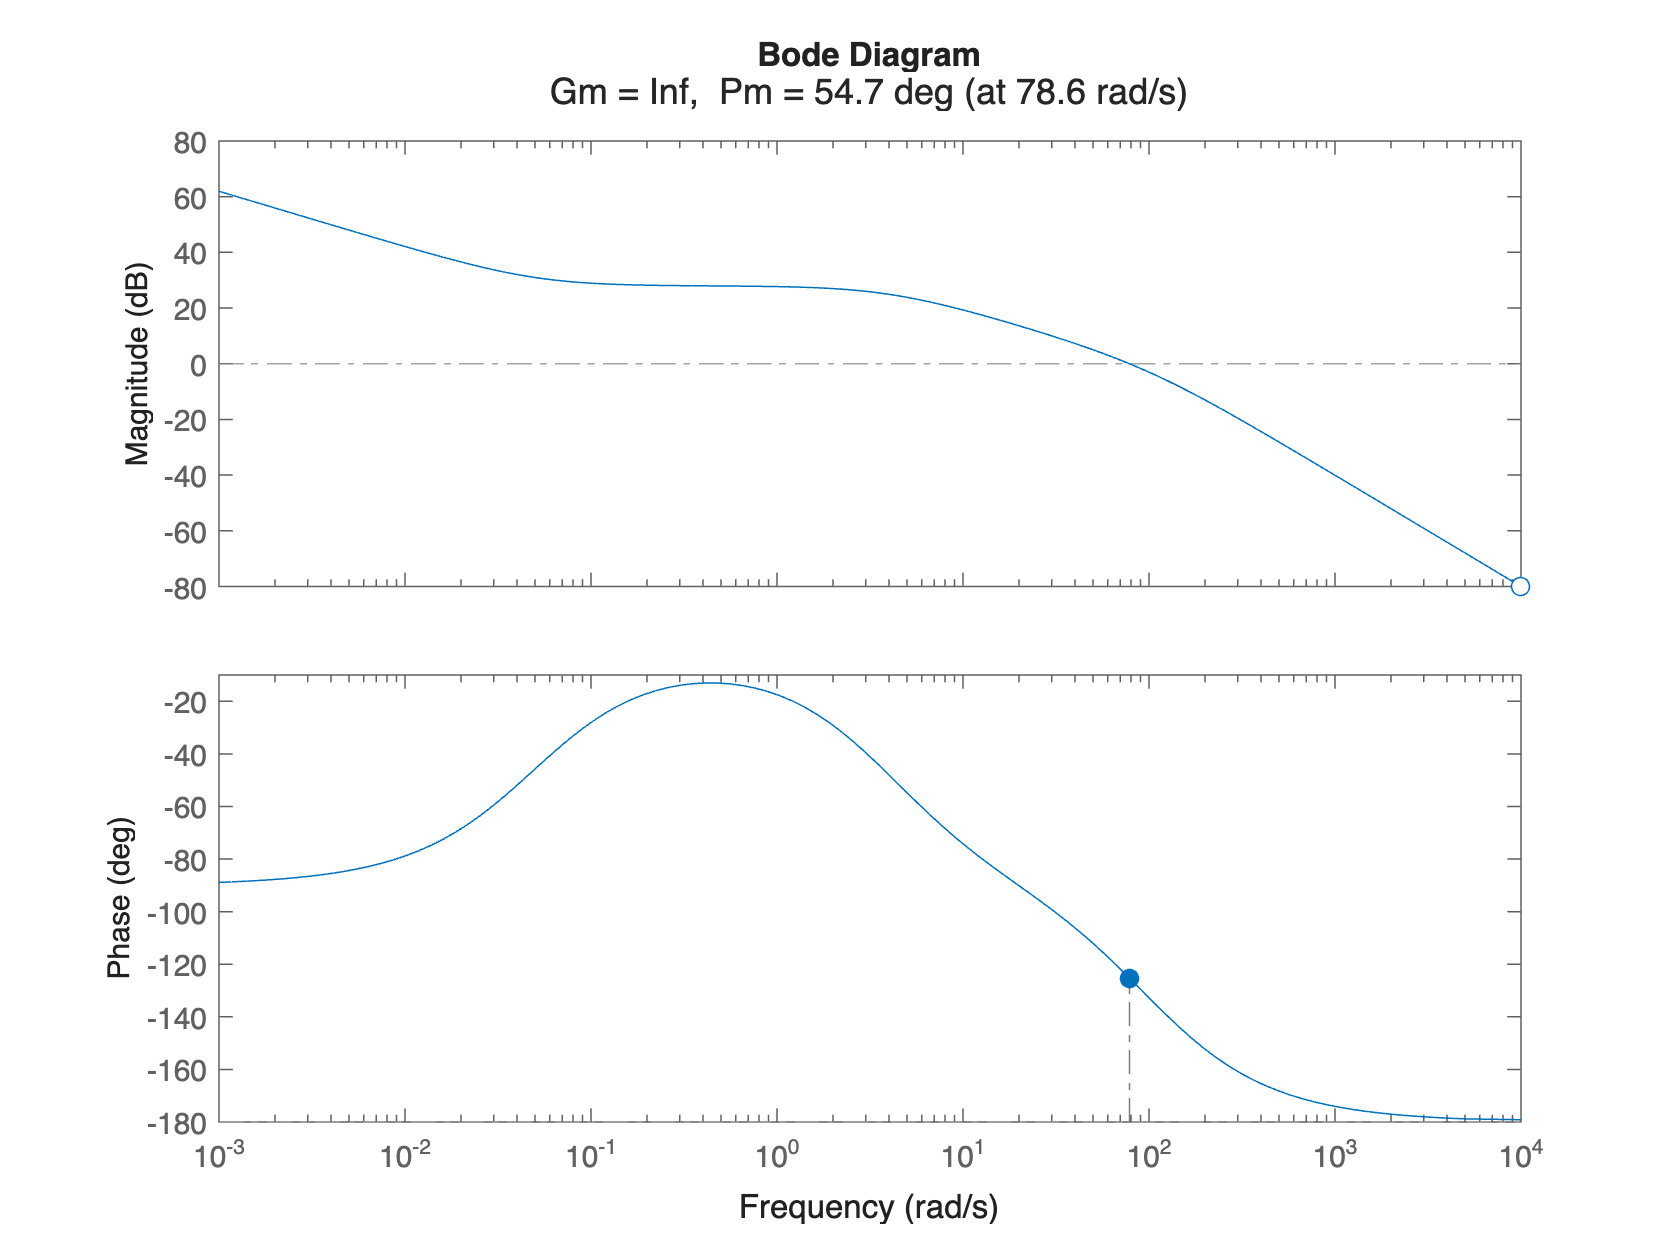

figure;margin(L2s)

#### **Tuning the Solution**

Let's tune the candidate solution using the Control System Designer app

controlSystemDesigner(Gs, Cs)


Refer to `ControlSystemDesignerSession_FINAL_TUNING_V1.mat`

### A Different Solution

#### Design by Cancellation

Let's cancel the plant dynamics using the controller $C_2(s)$:


$$C(s) = \frac{\mu_C}{s}\,\frac{(1+0.125\,s)^2}{(1+20\,s)}$$


Thus


$$L(s) = C(s) \cdot G(s) = \frac{4.815\,\mu_C}{s}$$


Consider the expression of the **frequency response magnitude**:


$$\left| L_2(j \omega) \right| = 4.815\cdot \mu_C \cdot \frac{ 1}{\omega}$$


and compute the **asymptotic** **approximation**, according to the rules explained in **Part 8, pp. 21 - 35** of the course material


$$ \left|L_2(j \omega) \right|_{\text{dB}} \approx 20\,\log_{10} 4.815\cdot \mu_C -20\,\log_{10}\omega  = 13.65+20\,\log_{10} \mu_C  -20\,\log_{10}\omega$$


The requirements (Q1.1) and (Q1.4) have been meet. In order to fulfill the requirements (Q1.2) and (Q1.3) we have to fine tuning $\mu_C$


$$\left\{ \begin{array}{rcl}
\left|L_2(j \omega) \right|_{\text{dB}} \ge +26 \,,\; \forall \omega \in \left[0.1\,,\; 1.0\right] &\Longrightarrow & \left|L_2(j 1.0) \right|_{\text{dB}} \approx 13.65+20\,\log_{10} \mu_C  -20\,\log_{10}1.0 \ge 26 \\
\left|L_2(j \omega) \right|_{\text{dB}} \le -28 \,,\; \forall  \omega \in \left[600.0\,,\; 1200.0\right] & \Longrightarrow & \left|L_2(j 600) \right|_{\text{dB}} \approx
13.65+20\,\log_{10} \mu_C  -20\,\log_{10}600 \le -28
\end{array} \right.$$


Thus, after some manipulation:


$$\left\{ \begin{array}{rcl}
\log_{10} \mu_C  &\ge&\frac{ 26-13.65}{20} \,\approx\, 0.6175 \\
\log_{10} \mu_C   &\le& \frac{-28-13.65+20\,\log_{10}600}{20} \,\approx\, 0.6957
\end{array} \right. \quad \Longrightarrow \quad 4.1448 < \mu_C < 4.9625$$


Thus, a feasible solution is 


$$\bar \mu_C = 4.6$$


**Feasibility by Visual Inspection on the Bode Diagram**

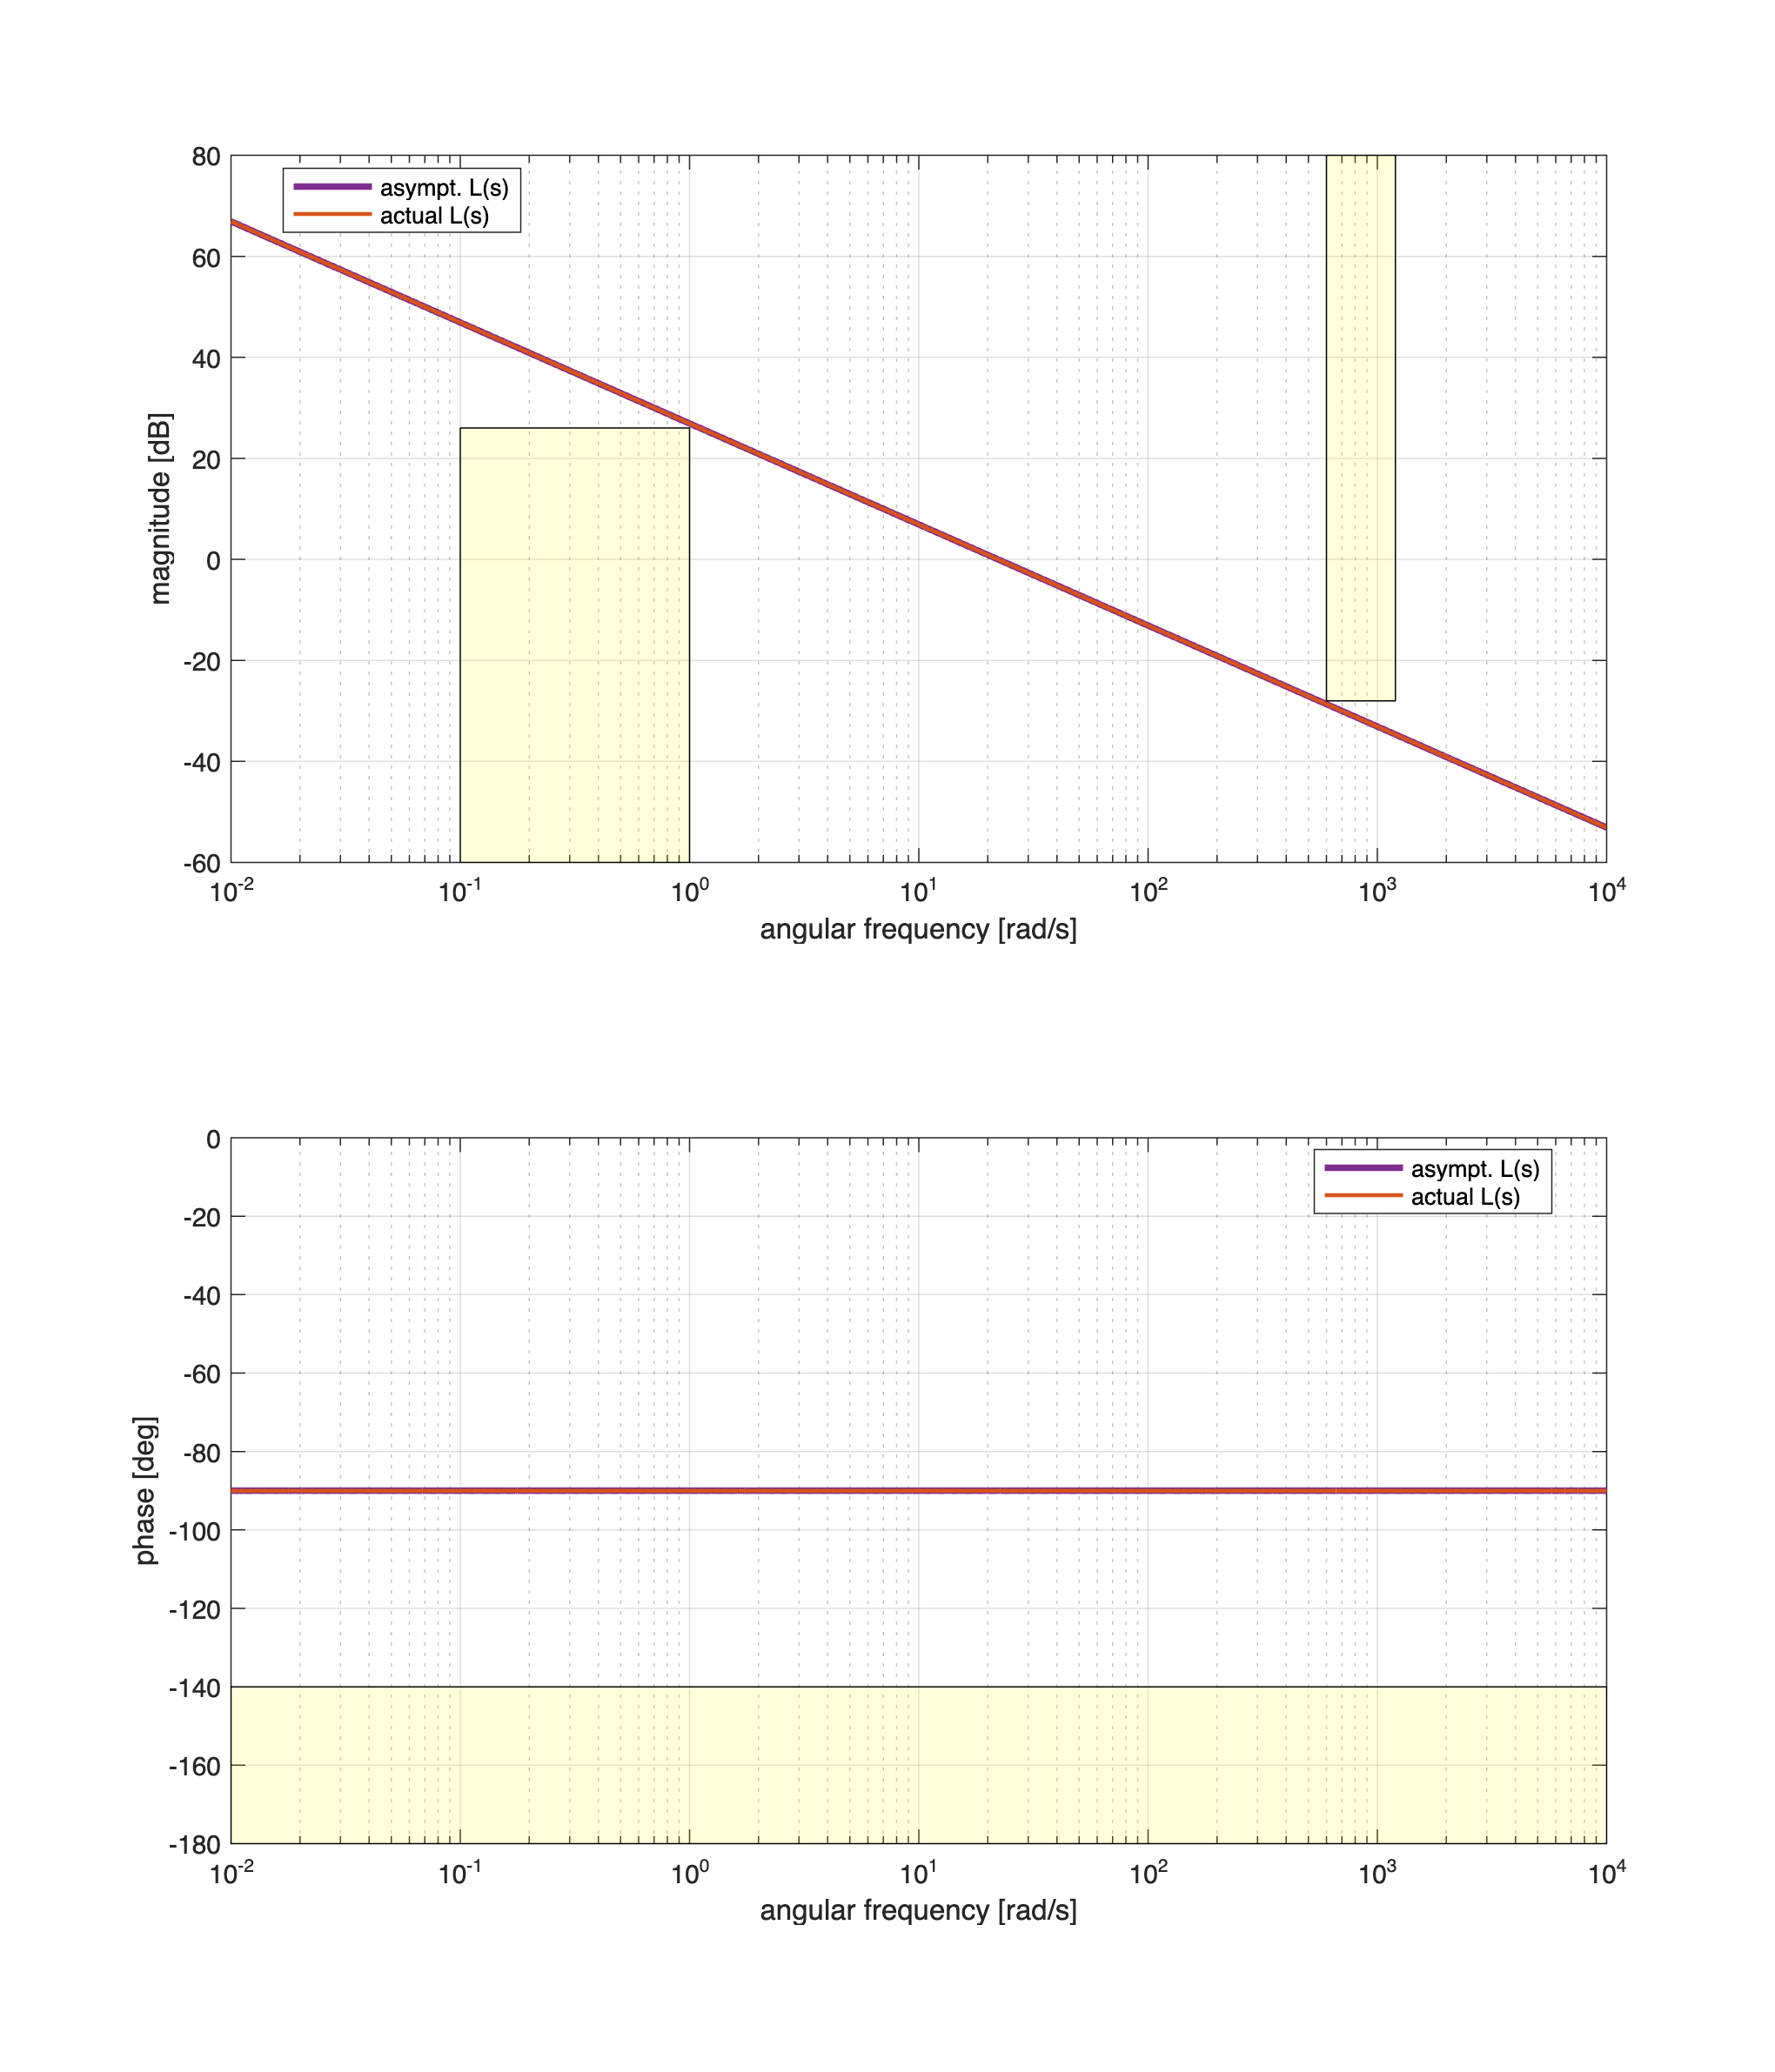

muC1 = 4.6; % improve the amplification
C1s = muC1/s; % a pure I controller (the static controller)
C2s = (1+0.125*s)^2/(1+20*s); % the dynamic controller
Cs = C1s * C2s;

Ls = minreal(Cs*Gs); % the open-loop TF
zL = zero(Ls);
pL = pole(Ls);

omVALS = logspace(-2,4, 1e5); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-1 and 10^2 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                  % for the actual diagrams

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

[hax1, hax2] = drawBodediagrams(Ls, omVALS, Bcolors(3, :), 2.5, '-', ...
                       Bcolors(6, :), 1.5, '-', hf);

% the (Q1.2) constraint
minOmega1 = 0.1;
maxOmega1 = 1.0;
LMINdB = +26; % dB
YLIMs = ylim(hax1);
Vert1 = [minOmega1 , YLIMs(1); minOmega1 , LMINdB; ...
         maxOmega1 , YLIMs(1); maxOmega1 , LMINdB];
Faces1 = [1  2  4  3];
hold on;
patch(hax1, 'Faces',Faces1,'Vertices',Vert1,...
        'FaceColor','yellow','FaceAlpha',.15);
% the (Q1.3) constraint
minOmega2 = 600.0;
maxOmega2 = 1200.0;
LMAXdB = -28; % dB
YLIMs = ylim(hax1);
Vert2 = [minOmega2 , LMAXdB; minOmega2 , YLIMs(2) ; ...
         maxOmega2 , YLIMs(2); maxOmega2 , LMAXdB];
Faces2 = [1  2  3  4];
patch(hax1, 'Faces',Faces2,'Vertices',Vert2,...
        'FaceColor','yellow','FaceAlpha',.15);

% the (Q1.4) constraint
ylim(hax2, [-180, 0]);
XLIMs = xlim(hax2);
YLIMs = ylim(hax2);
minOmega2 = min(XLIMs);
maxOmega2 = max(XLIMs);
argLMIN = -140; % arg(L(j omega)) >= -140 <==> phase margin >= 40

Vert2 = [minOmega2 , YLIMs(1); minOmega2 , argLMIN ; ...
         maxOmega2 ,argLMIN ; maxOmega2 , YLIMs(1)];
Faces2 = [1  2  3  4];
patch(hax2, 'Faces',Faces2,'Vertices',Vert2,...
        'FaceColor','yellow','FaceAlpha',.15);


legend(hax1,  'asympt. L(s)', 'actual L(s)', ...
             'Location', 'best');

legend(hax2,  'asympt. L(s)', 'actual L(s)', ...
             'Location', 'best');

#### The Effective Phase and Gain Margins

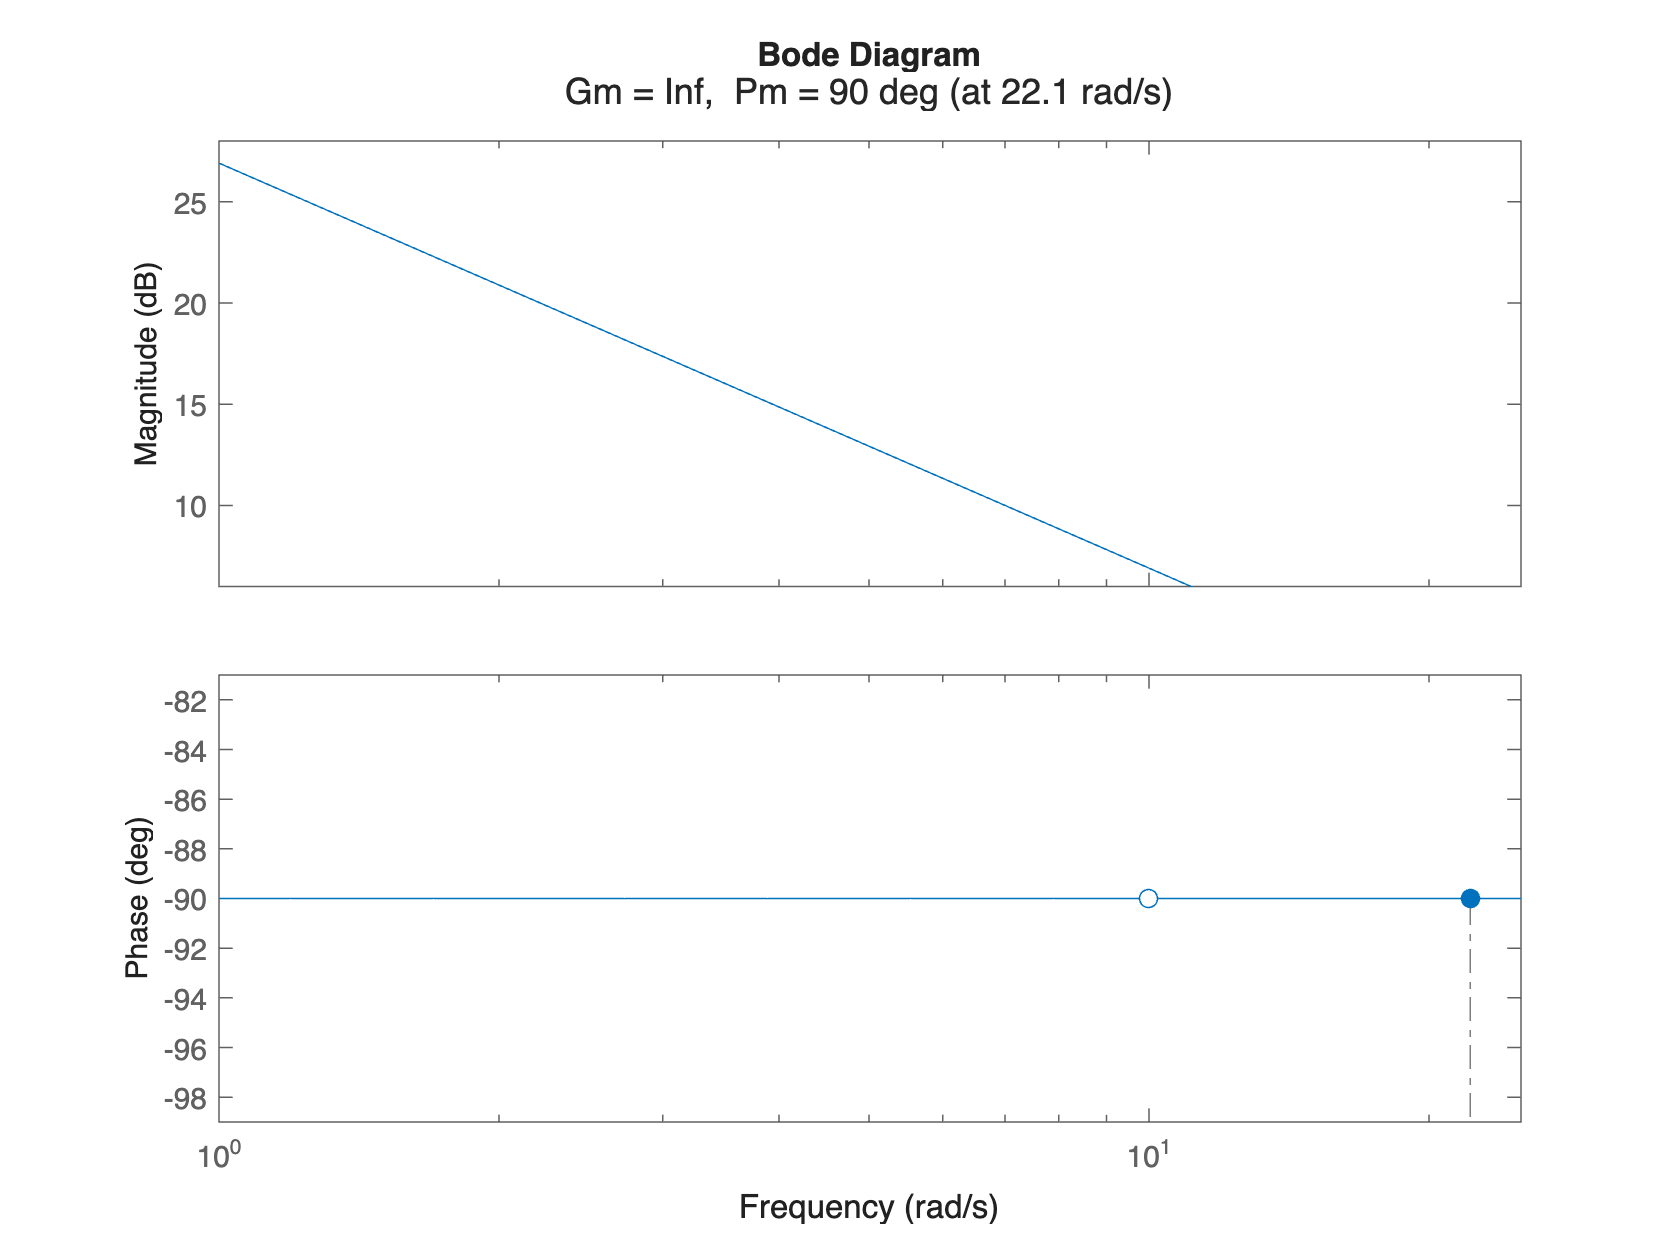

figure;margin(Ls)

#### **Tuning the Solution**

Let's tune the candidate solution using the Control System Designer app

controlSystemDesigner(Gs, Cs)


Refer to `ControlSystemDesignerSession_FINAL_TUNING_V2.mat`